# Variants of Vanilla MPC 

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India  

## Introduction 

In the previous lessons in this module, we have derived a vanilla MPC formulation that can be used for servo and regulatory control of any multi-variable system. In this lesson we present variants that are used in industrial settings. The **learning objectives** are 

- Develop output tracking vanilla MPC formulation 

- Include input rate penalty term in the MPC loss function 

- Introduce the concept of control horizon 

## MPC Cost Function and Input Constraints  

.  To make connections with the classical optimal control theory, we started with the regulatory cost function that controls the system at the origin 

    $J\left\lbrack x\left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack ={{\left\|z\left(k+p\right)\right\|}^2 }_{W_{\infty } } +\sum_{j=0}^{p-1} \left\lbrace {{\left\|z\left(k+j\right)\right\|}^2 }_{W_x } +{{\left\|u\left(k+j|k\right)\right\|}^2 }_{W_u } \right\rbrace$  ------(1)

and arrived at a time varying target tracking objective

$J\left\lbrack y\left(k\right),\hat{x} \left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack ={{\left\|z\left(k+p\right)-x_s \left(k\right)\right\|}^2 }_{W_{\infty } } +\sum_{j=0}^{p-1} \left\lbrace {{\left\|z\left(k+j\right)-x_s \left(k\right)\right\|}^2 }_{W_x } +{{\left\|u\left(k+j|k\right)-u_s \left(k\right)\right\|}^2 }_{W_u } \right\rbrace$  ------(2)

that can handle time varying output setpoint in the face of unknown unmeasured disturbances for a controlling a system that evolves as 

    $\begin{array}{l}
x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)+\Gamma_d \;d\left(k\right)\\
y\left(k\right)=C\;x\left(k\right)\;+v\left(k\right)
\end{array}$  ------(3)

where $y\left(k\right)$ represents measured and controlled output. The key to achieve offset free control is to compute target state and target input $\left(x_s \left(k\right),u_s \left(k\right)\right)$ using the setpoint for controlled outputs, $r\left(k\right)$, and the model plant mismatch signal, 

$\begin{array}{l}
\hat{d} \left(k\right)=y\left(k\right)-\hat{y} \left(k\right)=y\left(k\right)-C\;\hat{x} \left(k\right)\\
\;\hat{x} \left(k\right)=\Phi \hat{x} \left(k-1\right)+\Gamma u\left(k-1\right)
\end{array}$.   ------(4)

In fact, we demonstrated that the vanilla MPC formulation is also able to perform servo and regulatory control a nonlinear dynamic system governed by 

$\;\;\;U\left(k\right)=u\left(k\right)+U_s \;\;\;\textrm{and}\;D\left(k\right)=d\left(k\right)+D_s$ ------(5)

$X\left(k+1\right)=F\left(X\left(k\right),U\left(k\right),D\left(k\right)\right)$  ------(6) 

 $y\left(k\right)=C\left(X\left(k\right)-X_s \right)\;$  ------(7) 

### Inclusion of Input Rate Penalty 

      In Module 3, we have introduced ***hard*** constraints on rate of change of manipulated inputs, i.e. 

$\;\;{\Delta u}_L \le \Delta u\left(k+j|k\right)\le {\Delta u}_H \;\;\textrm{for}\;\;j=0,1,2,\ldotp \ldotp \ldotp \ldotp p-1$   -------(8)

where

$\Delta u\left(k+j|k\right)=\;u\left(k+j|k\right)-u\left(k+j-1|k\right)\;\textrm{for}\;\;j=1,2,\ldotp \ldotp \ldotp \ldotp p-1$  ------(9)

$\Delta u\left(k|k\right)=\;u\left(k|k\right)-u\left(k-1\right)$  ------(10)

Instead of introducing such hard constraints on the rate of change of inputs, a penalty terms of the form 


$$\sum_{j=0}^{p-1} {{\left\|\Delta u\left(k+j|k\right)\right\|}^2 }_{W_{\Delta u} }$$


is added to the MPC loss function where $W_{\Delta u}$ is a positive definite matrix. The modified loss function in this case become

$J\left\lbrack y\left(k\right),\hat{x} \left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack ={{\left\|z\left(k+p\right)-x_s \left(k\right)\right\|}^2 }_{W_{\infty } } +\sum_{j=0}^{p-1} \left\lbrace {{\left\|z\left(k+j\right)-x_s \left(k\right)\right\|}^2 }_{W_x } +{{\left\|u\left(k+j|k\right)-u_s \left(k\right)\right\|}^2 }_{W_u } \right\rbrace +{{\left\|\Delta u\left(k+j|k\right)\right\|}^2 }_{W_{\Delta u} }$ ----(11)

and variant of vanilla MPC, which is similar to industrial versions of MPC, can be stated as follows  


$$\;$$
  
$${\mathrm{U}}_p^* \left(k\right)=\overset{\arg \;\min }{{\mathrm{U}}_p \left(k\right)} \;\;\;J\left\lbrack y\left(k\right),\hat{x} \left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack$$
  

Subject To

$\begin{array}{l}
z\left(k+j+1\right)=\Phi z\left(k+j\right)+\Gamma u\left(k+j|k\right)\;\;\textrm{for}\;j=0,1,\ldotp \ldotp \ldotp ,p-1\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{with}\;\textrm{initial}\;\textrm{condition}\;\;z\left(k\right)=\hat{x} \left(k\right)
\end{array}$  -------(12)

     $u_L \le u\left(k+j|k\right)\le u_H$   for$j=0,1,2,\ldotp \ldotp \ldotp \ldotp p-1$  

To include the input rate penalty in the QP formulation of MPC, recall the expression that we developed by staking $\Delta u\left(k+j|k\right)$ for constraint handling 

$\Delta U_f \left(k\right)=\left\lbrack \begin{array}{c}
u\left(k\right)-u\left(k-1\right)\\
u\left(k+1\right)-u\left(k\right)\\
\cdots \\
u\left(k+p-1\right)-u\left(k+p-2\right)
\end{array}\right\rbrack =\Psi U_f \left(k\right)-\Psi_0 u\left(k-1\right)$ ------(13)

where

 $\Psi =\left\lbrack \begin{array}{cccc}
I & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack \\
-I & I & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack \\
\cdots  & \cdots  & \cdots  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack  & \cdots  & -I & I
\end{array}\right\rbrack$   and $\Psi_0 =\left\lbrack \begin{array}{c}
I\\
\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack \\
\cdots \\
\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack 
\end{array}\right\rbrack$   ------(14)

Defining block diagonal matrix 

${\mathbf{W}}_{\Delta U} =\left\lbrack \begin{array}{cccc}
W_{\Delta u}  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack  & \ldotp \ldotp \ldotp  & \left\lbrack 0\right\rbrack \\
\left\lbrack 0\right\rbrack  & W_{\Delta u}  & \ldotp \ldotp \ldotp  & \left\lbrack 0\right\rbrack \\
 &  & \ddots  & \\
\left\lbrack 0\right\rbrack  & \left\lbrack 0\right\rbrack  & \ldotp \ldotp \ldotp  & W_{\Delta u} 
\end{array}\right\rbrack$  ------(15)

we need to the following include term in the cost function 

 ${\left(\Delta U_f \left(k\right)\right)}^T \;\;{\mathbf{W}}_{\Delta U} \;\Delta U_f \left(k\right)={\left(\Psi U_f \left(k\right)-\Psi_0 u\left(k-1\right)\right)}^T {\mathbf{W}}_{\Delta U} \;\left(\Psi U_f \left(k\right)-\Psi_0 u\left(k-1\right)\right)$  ------(16)

Since, $u\left(k-1\right)$ is a known vector at instant k, it is sufficient to include the following term in the QP loss function 


$${\left(\Psi U_f \left(k\right)\right)}^T {\mathbf{W}}_{\Delta U} \;\left(\Psi U_f \left(k\right)\right)\;-2{\left(\Psi_0 u\left(k-1\right)\right)}^T {\mathbf{W}}_{\Delta U} \Psi U_f \left(k\right)$$


Thus, the QP loss function gets modified as follows 

$J\;\;\;=\frac{1}{2}{{\;U}_f \left(k\right)}^T \;\mathbf{H}\;U_f \left(k\right)+{F\left(k\right)}^T U_f \left(k\right)$  -----(17a) 

$\begin{array}{l}
\mathbf{H}=2\left({S_u }^T {\mathbf{W}}_X S_u +{\mathbf{W}}_U +\Psi^T {\mathbf{W}}_{\Delta U} \Psi \right)\;\\
F\left(k\right)=2\left({{S_u }^T \mathbf{W}}_X S_x \right)\;x\left(k\right)\;-2\left(\Psi^T \;{\mathbf{W}}_{\Delta U} \Psi_0 \right)u\left(k-1\right)-2\;\left({\mathbf{W}}_U {\mathbf{I}}_U \right)u_s -{2\left(S_u \right)}^T {\mathbf{W}}_X \left({\mathbf{I}}_X \right)x_s 
\end{array}$------(17b)

Let us investigate the influence input rate penalty has on the closed loop behavior of the Q-Tank system. 

### Quadruple Tank Simulation with MPC using Input Rate Penalty

Let us investigate the influence input rate penalty has on the closed loop behavior of the Q-Tank system. We can run the following code using run button.

 
clear all 

N = 301 ;      % Simulation run time
global QTank U_k D_k

**Task 1**: Recall that Q Tank process has two steady state operating points. Select the operating point for Q Tank process.  This will load quadruple tank parameters and steady state corresponding to the selected operating point. We can see QTank data structure in workspace. Set it to Minimum Phase initially.

operating_pt=1;

% Load quadruple tank parameters and steady state 
% The following file loads QTank data structure 
if operating_pt==1
load QTank_MinPhase_Model
else
 load QTank_NonMinPhase_Model 
end

 We then Initialize discrete dynamic model matrices for MPC formulation using the model matrices

% Initialization of linear discrete time model for plant simulation 

phy = QTank.phy ;
gam = QTank.gama_u  ;
gam_d = QTank.gama_d  ;
[n_st,n_ip] = size(gam) ;
C_mat = [ 1 0 0 0 ; 0 1 0 0] ;  % Levels are assume to be directly measured 
[n_op, nx ] = size(C_mat)  ;         
[n_st,n_ip] = size(gam) ;

% Initialization of Internal model for MPC 
mpc.phy = phy ;   
mpc.gam = gam ; 
mpc.C_mat = C_mat ; 
[mpc.n_st,mpc.n_ip] = size(mpc.gam) ;
[mpc.n_op, nx] = size(mpc.C_mat) ; 


**MPC Tuning Parameters**

**Task 2: **Set the prediction horizon mpc.n_pred to interval >= 50**. **Set it to 50 initially

mpc.n_pred =50; 

**Task 3: **We have created the variables ${\textrm{mpc}\ldotp W}_u$, the **Input Weighting Matrix, **${\textrm{mpc}\ldotp W}_{\Delta u}$, **Input Rate Weighting Matrix  and **${\textrm{mpc}\ldotp W}_y$ the **Output Weighting Matrix and **$W_x$, the State Weighting Matrix are given as below

 $W_y =\left\lbrack \begin{array}{cc}
\alpha_1  & 0\\
0 & \alpha_2 
\end{array}\right\rbrack$,  $W_u =\left\lbrack \begin{array}{cc}
\beta_1  & 0\\
0 & \beta_2 
\end{array}\right\rbrack$ and  $W_{\Delta u} =\left\lbrack \begin{array}{cc}
\gamma_1  & 0\\
0 & \gamma_2 
\end{array}\right\rbrack$

The state weighting matrix $W_x$ is then computed as


$$W_x =C^T W_y C$$


beta(1)=1;
beta(2)=1;
disp('Input weighting matrix')

Input weighting matrix


mpc.Wu = diag(beta);
gamma(1)=10000;
gamma(2)=10000;
disp('Input Rate weighting matrix')

Input Rate weighting matrix


mpc.Wdelu = diag(gamma) ;% Input Rate weighting matrix. Note: Effect is seen only if large weighting is used 

Note that the effect of rate weighting is seen only if large weighting is used 

alpha(1)=10;
alpha(2)=10;
disp('Output weighting matrix')

Output weighting matrix


mpc.Wy = diag(alpha);  % Output weighting matrix
mpc.Wx = mpc.C_mat' * mpc.Wy * mpc.C_mat ;%State Weighting Matrix
%Bounds on Inputs
mpc.u_H = [5 5]' - QTank.Us ;  % Physical Input bounds low are 0 and 5 Volts 
mpc.u_L = [0 0]' - QTank.Us ;  % Steady state inputs are [3 3] for nonminimum phase and [3.15 3.15] for non-minimum phase
mpc.deluL = [] ; mpc.deluH = [] ; 


**Generation of  QP matrices**

Note: A function (Gen_QP_Matrices_Tracking_delU) is used to generate QP matrices.

[mpc] = Gen_QP_Matrices_Tracking_delU( mpc ) ;

 **Controller related parameters and matrices **

mpc.xkhat = zeros(mpc.n_st,N);
mpc.xs_k = zeros(n_st,N);   % Array to save target states 
mpc.us_k = zeros(n_ip,N) ;  % Array to save target inputs  
mpc.xkhat = zeros(n_st,N);
mpc.yhat = zeros(n_op,N) ; 
mpc.dkhat = zeros(n_op,N); % Model plant mismatch signal 
mpc.dkhat_f = zeros(n_op,N); % Filtered Model plant mismatch signal 
mpc.phy_d = 0.9* eye(n_op) ;   % Disturbance filter 

% Matrices for simulating system dynamics 

xk = zeros(n_st,N);
uk = zeros(n_ip,N) ;
yk = zeros(n_op,N);
yk(:,1) = C_mat * xk(:,1) ; 
dk = zeros(1,N) ;
rk_f = zeros(n_op,N);  % Setpoint filter parameters 
phy_r = 0.0 * eye(n_op) ;

** Disturbance input **

A time varying disturbance input signal is generated such that initially it is set to zero. Then changed from it's initial value to 0.25 for ($\left.k\ge 50\right)\;$.

for k = 1:N
    if ( k < 50 )
        dk(k) = 0 ;
    else
        dk(k) = 0.25 ;  % Introduce disturbance change at k = 50
    end
end


**Closed loop simulations using QP-LMPC under model-plant mismatch **

Optimal controller output is obtained using MATLAB function [quadprog](https://in.mathworks.com/help/optim/ug/quadprog.html). [`x`](https://in.mathworks.com/help/optim/ug/quadprog.html#mw_4fdf75e1-35ab-4c9d-aaf4-c81f677d0f62)` = quadprog(`[`H`](https://in.mathworks.com/help/optim/ug/quadprog.html#bssh6y6-1-H)`,`[`f`](https://in.mathworks.com/help/optim/ug/quadprog.html#d126e155087)`,`[`A`](https://in.mathworks.com/help/optim/ug/quadprog.html#bssh6y6-1_sep_shared-A)`,`[`b`](https://in.mathworks.com/help/optim/ug/quadprog.html#bssh6y6-1_sep_shared-b)`,[],[],[],[],options)` as done in earlier exercises.  Controller calculations at instant k are done assuming state vector is perfectly measured. Quadruple tank Plant Simulation from$k\;\textrm{to}\;k+1$is done using using nonlinear ode model or discrete linear model. Plant model mismatch signal is generated as follows


$$\hat{d} \left(k\right)=y\left(k\right)-C\hat{\mathrm{x}} \left(k\right)$$


This is then filtered using a first order filter 


$$\hat{d_f } \left(k+1\right)=\Phi_d \hat{d_f } \left(k\right)+\left(I-\Phi_d \right)\hat{d} \left(k\right)$$


for k = 1:N-1
    kT(k) = (k-1);
    if ( k < 50 )
        rk = [0 0]' ;
    else
        rk = [ -3 4 ]' ;
    end

**Tracking Time Varying Setpoints **

As seen in the previous lesson, a time varying reference input signal is generated such that initially it is set to zero for both the outputs.  Then changed from it's initial value to$r\left(k\right)=\left\lbrack -3\;\;4\right\rbrack$ for $k\ge 50$. Set point is also filtered as


$$r_f \left(k+1\right)=\Phi_r r_f \left(k\right)+\left(I-\Phi_r \right)r\left(k\right)$$


 rk_f(:,k+1) = phy_r * rk_f(:,k) + (eye(n_op) - phy_r) * rk   ;

**Generation of  QP matrices**

Note: A function (MPCQP_StateSpace_delU) is used to generate QP matrices.

    % MPC implementation at instant k
  [mpc, u_k ] = MPCQP_StateSpace_delU( mpc, yk(:,k), rk_f(:,k+1), k ) ;
  mpc.uk = u_k ;

Quadruple Tank Plant Simulation from k to k+1 can be done using using discrete linear model or a nonlinear ODE model.

**Task 4:** Select Plant_Sim as Nonlinear for simulating Q Tank process using a nonlinear ODE model.

Plant_Sim =1  ; 
  if (Plant_Sim )
        uk(:,k) = mpc.uk;
        xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) + gam_d * dk(k)  ;
       yk(:,k+1) = C_mat * xk(:,k+1) ;
    else
        uk(:,k) = mpc.uk ;
        U_k = QTank.Us + mpc.uk ;
        D_k =  QTank.Ds + dk(k)  ;
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;   % Nonlinear plant simulation
          xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
         yk(:,k+1) = C_mat * xk(:,k+1) ;
      end
 end
uk(:,N) = uk(:,N-1) ;
kT(N) = N-1 ;
mpc.dkhat(:,N) = mpc.dkhat(:,N-1) ; 
mpc.us_k(:,N) = mpc.us_k(:,N-1) ;
mpc.xs_k(:,N) = mpc.xs_k(:,N-1) ;


**MPC QP controller function**

Note: A function (MPCQP_StateSpace_delU) is used to generate QP matrices.

**Display Simulation Results **

Observe the figures below for state profiles tracking control, time varying set-point tracking control for outputs, inputs, model plant mismatch signal, unmeasured disturbance input, target State Profiles and target Input Profiles.

% Display results
Set_Graphics_Parameters ;
Xk = QTank.Xs + xk ;   Uk = QTank.Us + uk ; Dk = QTank.Ds + dk ;
Yk = yk + C_mat * QTank.Xs ;  Rk_f = rk_f + C_mat * QTank.Xs ;
u_limit = [mpc.u_L(1)*ones(N,1) mpc.u_H(1)*ones(N,1)]  ;

**Controlled output profiles **

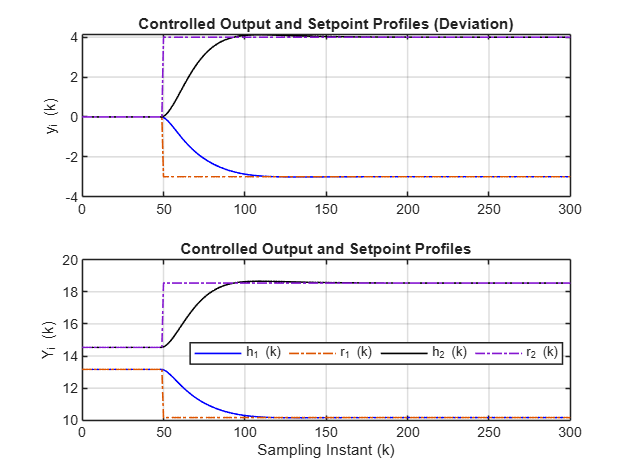

figure, subplot(211), 
plot(kT, yk(1,:), 'b',  kT, rk_f(1,:), '-.', kT, yk(2,:), 'k', kT, rk_f(2,:), '-.'), grid
title('Controlled Output and Setpoint Profiles (Deviation)'), ylabel('y_i (k)')
subplot(212), plot(kT, Yk(1,:), 'b',  kT, Rk_f(1,:), '-.', kT, Yk(2,:), 'k', kT, Rk_f(2,:), '-.'), grid
xlabel('Sampling Instant (k)'), ylabel('Y_i (k)')
legend('h_1 (k)', 'r_1 (k)', 'h_2 (k)', 'r_2 (k)', 'Orientation','horizontal','Location','Best')
title('Controlled Output and Setpoint Profiles')

**Manipulated input profiles**

figure, subplot(211), stairs(kT, mpc.us_k(1,:)', '-.b','LineWidth',1), grid
hold on
stairs(kT, uk(1,:)', 'b','LineWidth',1)
stairs(kT, mpc.us_k(2,:)', '-.k','LineWidth',1)
stairs(kT, uk(2,:)', 'k','LineWidth',1)
stairs(u_limit, '-.r', 'LineWidth',1)
axis([0 N -3.5 2.5])
hold off
ylabel('u_i (k)'), title('Target Input Profiles and Deviation Input profiles')
legend( 'us_1', 'u_1', 'us_2', 'u_2', 'Orientation','horizontal','Location','Best')
subplot(212), stairs(kT, Uk(1,:)', 'b','LineWidth',1),  grid
hold on, stairs(kT, Uk(2,:)', 'k','LineWidth',1),
stairs(u_limit+QTank.Us', '-.r', 'LineWidth',1), hold off
axis([0 N 0 5.5]), ylabel('u_i (k)')
title('Manipulated Input Profiles')
legend( 'U_1 (k)', 'U_2 (k)','Orientation','horizontal','Location','Best')

**Disturbance input and Model Plant Mismatch profiles **

figure, subplot(211), stairs( kT, Dk,'LineWidth',1 ), grid
xlabel('Sampling Instant (k)'), ylabel('d(k)')
title(' Unmeasured Disturbance (deviation) Profile')
subplot(212), stairs( kT, mpc.dkhat_f','LineWidth',1 ), grid
xlabel('Sampling Instant (k)'), ylabel('dkhat_i (k)')
title('Model plant mismatch signal')

** System State profiles and MPC internal model profiles  **

figure, plot(kT, Xk(1,:), kT, Xk(2,:), kT, Xk(3,:), kT, Xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('h_1 (k)', 'h_2 (k)', 'h_3 (k)', 'h_4 (k)', 'Orientation','horizontal','Location','Best')
title('System State Profiles')
figure, plot(kT, mpc.xs_k, '-.r', kT, mpc.xkhat, 'k'), grid
title('RED: Target States   BLACK: MPC Model State Estimates')
xlabel('Sampling Instant (k)'), ylabel('xs_i(k) and x_i(k)')
% <--------------MPC QP function---------------
% Inputs: Measurement and setpoint at instant k 
% Output: Manipulated input at instant k 

function [mpc, u_k ]  = MPCQP_StateSpace_delU(mpc, y_k, r_k, k)

% Controller calculations at instant k
mpc.yhatk(:,k) = mpc.C_mat * mpc.xkhat(:,k) ;
mpc.dkhat(:,k) = y_k - mpc.yhatk(:,k) ;
mpc.dkhat_f(:,k+1) = mpc.phy_d * mpc.dkhat_f(:,k) + (eye(mpc.n_op) - mpc.phy_d) * mpc.dkhat(:,k) ;
% Estimate model plant mismatch and filter it using unity gain filter

options = optimoptions('quadprog', 'display', 'off');

% Target state computations by solving QP
Fsk_vec = mpc.Fs_mat * ( r_k - mpc.dkhat_f(:,k+1) ) ;
[us_k_QP, fsval] = quadprog(mpc.Hs_mat, Fsk_vec,mpc.As_mat, mpc.bs_vec, [],[],[],[],[], options )  ;
mpc.us_k(:,k) = us_k_QP ;
mpc.xs_k(:,k) = inv(eye(mpc.n_st) - mpc.phy) * mpc.gam * mpc.us_k(:,k) ;

b_vec = mpc.F_vec ;

if ( k == 1)
    Fk_vec = mpc.F_mat*mpc.xkhat(:,k) ;
else
    % Note that mpc.uk corresponds to uk(:,k-1) before we compute u_k at instant k 
    Fk_vec = mpc.F_mat*mpc.xkhat(:,k) - 2 * mpc.psi_mat' * mpc.WdelU_mat * mpc.psi_0_mat * mpc.uk ;
end
Fk_vec = Fk_vec - 2 * mpc.WU_mat * mpc.Iu_mat * mpc.us_k(:,k)  - 2 * mpc.Su_mat' * mpc.WX_mat * mpc.Ix_mat * mpc.xs_k(:,k) ;
[Uf_k,FVAL] = quadprog(mpc.H_mat, Fk_vec, mpc.A_mat, b_vec, [], [], [], [], [], options )  ;
u_k = Uf_k(1:mpc.n_ip) ;  % Implement only optimal u(k)

% Internal MPC model update from k to k+1
mpc.xkhat(:,k+1) = mpc.phy * mpc.xkhat(:,k) + mpc.gam * u_k  ;

end

We observe that the setpoints are tracked very well. The outputs have reached the desired values before $k=150$  . 

**Task 5:** Now change the operating point to Non-minimum phase and and again observe the results. Note the difference in settling time. We can make the response faster by changing the prediction horizon.

**Task 6: **Go to Task 2 and try changing the prediction horizon. Observe the effect on results

**Task 7: **Go to Task 3 and try changing the weighting matrices. Observe the effect on results. Can we make the outputs reach the desired values faster? 

**Task 8: **Try the above mentioned tasks by changing the plant simulation to nonlinear model in Task 4. What do you observe? Observe the plant model mismatch signal, it increases with nonlinear process simulation, however the controller can predict this and desired performance can be achieved.

### Control Horizon 

In the moving horizon framework, we only implement the first optimal input move ${u\left(k\right)=\;u}^* \left(k|k\right)$ from the set ${\mathrm{U}}_p^* \left(k\right)$ and the MPC problem is reformulated over the window $\left\lbrack k+1,k+p+1\right\rbrack$. One major concern in the real-time implementation is the time required for online computation. A commonly used approach to reduce computation time is to reduce the degrees of freedom available for the controller. Instead of using the decision variable set 

${\mathrm{U}}_p \left(k\right)=\left\lbrace u\left(k|k\right),u\left(k+1|k\right),\ldotp \ldotp \ldotp ,u\left(k+p-1|k\right)\right\rbrace$  ------(18)

we introduce change the decision variable set to 

${\mathrm{U}}_q \left(k\right)=\left\lbrace u\left(k|k\right),u\left(k+1|k\right),\ldotp \ldotp \ldotp ,u\left(k+q-1|k\right)\right\rbrace$   ------(19)

 where $q\ll p$ and introduce additional constraints on the future inputs as follows 

$u\left(k+j|k\right)=u\left(k+q-1|k\right)\;\;\textrm{for}\;j=q,q+1,\ldotp \ldotp \ldotp \ldotp ,p-1$  ------(20)

Here, *q *is referred to as the control horizon. With this modification, the vanilla MPC formulation changes as follows 


$$\;$$
  
$${\mathrm{U}}_q^* \left(k\right)=\overset{\arg \;\min }{{\mathrm{U}}_q \left(k\right)} \;\;\;J\left\lbrack y\left(k\right),\hat{x} \left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack$$
   

$J\left\lbrack y\left(k\right),\hat{x} \left(k\right),{\mathrm{U}}_q \left(k\right)\;\right\rbrack ={{\left\|z\left(k+p\right)-x_s \left(k\right)\right\|}^2 }_{W_{\infty } } +\sum_{j=0}^{p-1} {{\left\|z\left(k+j\right)-x_s \left(k\right)\right\|}^2 }_{W_x } +\sum_{j=0}^{q-1} {{\left\|u\left(k+j|k\right)-u_s \left(k\right)\right\|}^2 }_{W_u }$ ------(21)

Subject To

$\begin{array}{l}
z\left(k+j+1\right)=\Phi z\left(k+j\right)+\Gamma u\left(k+j|k\right)\;\;\textrm{for}\;j=0,1,\ldotp \ldotp \ldotp ,q-1\\
z\left(k+j+1\right)=\Phi z\left(k+j\right)+\Gamma u\left(k+q-1|k\right)\;\;\textrm{for}\;j=q,q+1,\ldotp \ldotp \ldotp ,p-1\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{with}\;\textrm{initial}\;\textrm{condition}\;\;z\left(k\right)=\hat{x} \left(k\right)
\end{array}$  ------(22)

     $u_L \le u\left(k+j|k\right)\le u_H$   for$j=0,1,2,\ldotp \ldotp \ldotp \ldotp q-1$   ------(23)

The concept of control horizon is illustrated for single input case in Figure 1. 

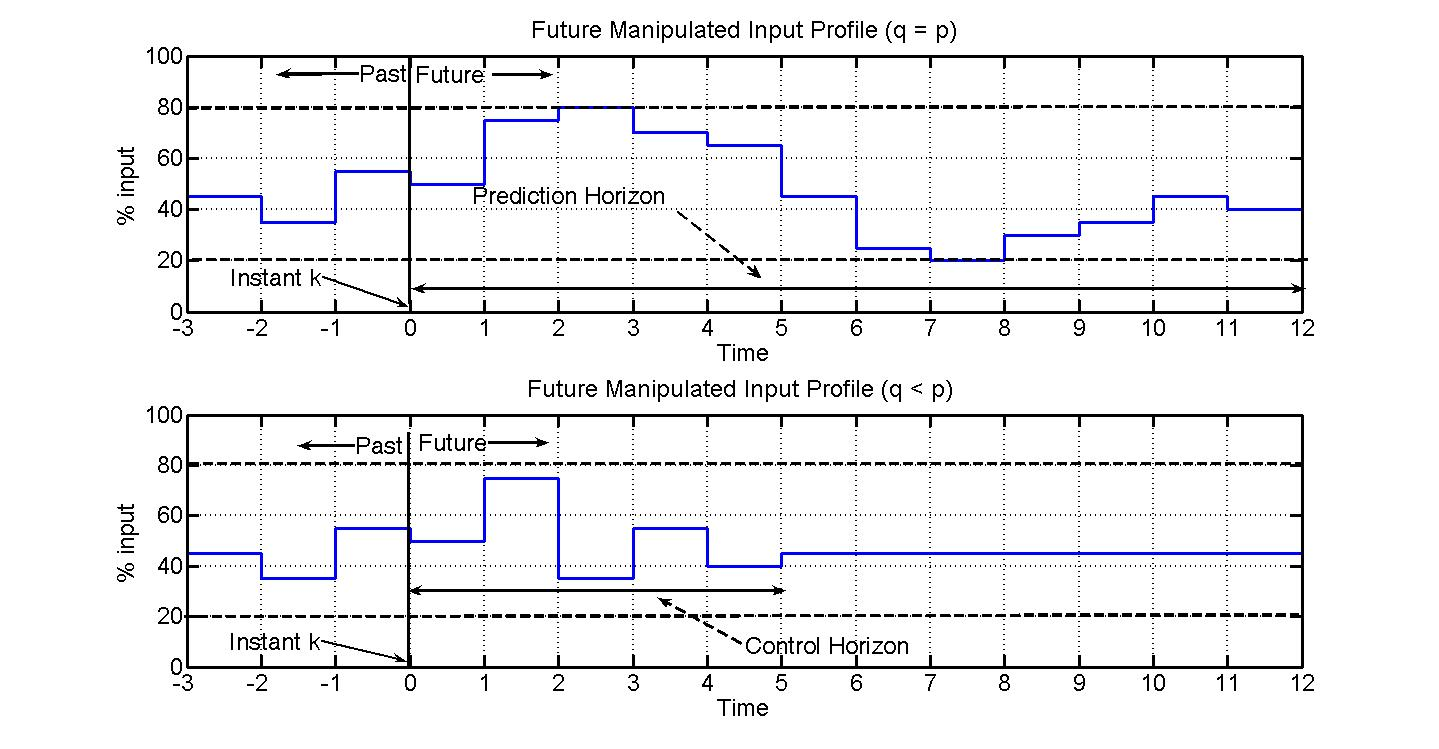

**Figure 1: Graphical illustration of control horizon **

To incorporate constraints arising from use of control horizon in MPC formulation,  let us define vector 

$U_q \left(k\right)=\;\left\lbrack \begin{array}{c}
u\left(k|k\right)\\
\ldotp \ldotp \ldotp \\
u\left(k+q-|k\right)
\end{array}\right\rbrack$  ------(24)

construct a matrix 

$\Psi_{\textrm{pq}} ={\left\lbrack \begin{array}{cccc}
I_m  & \left\lbrack 0\right\rbrack  & \ldotp \ldotp \ldotp  & \left\lbrack 0\right\rbrack \\
\left\lbrack 0\right\rbrack  & I_m  & \ldotp \ldotp \ldotp  & \left\lbrack 0\right\rbrack \\
\left\lbrack 0\right\rbrack  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & I_m \\
\left\lbrack 0\right\rbrack  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & I_m \\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
\left\lbrack 0\right\rbrack  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & I_m 
\end{array}\right\rbrack }_{\left(m\times p\right)\times \left(m\times q\right)}$ ------(25)

that maps $U_q \left(k\right)$ to a vector of dimension of $U_f \left(k\right)$ as follows 

$U_f \left(k\right)=\left\lbrack \begin{array}{c}
u\left(k|k\right)\\
\ldotp \ldotp \ldotp \\
u\left(k+q-1|k\right)\\
\ldotp \ldotp \ldotp \ldotp \\
u\left(k+q-1|k\right)
\end{array}\right\rbrack =\Psi_{\textrm{pq}} \;\left\lbrack \begin{array}{c}
u\left(k|k\right)\\
\ldotp \ldotp \ldotp \\
u\left(k+q-|k\right)
\end{array}\right\rbrack$ ------(26)

Using this transformation matrix, we can change the QP cost function as follows 

$\begin{array}{l}
\varphi \;\;\;=\frac{1}{2}{{\;U}_f \left(k\right)}^T \;\mathbf{H}\;U_f \left(k\right)+{F\left(k\right)}^T U_f \left(k\right)\\
\;\;\;\;\;\;\;=\frac{1}{2}{{\;U}_q \left(k\right)}^T \;\left({\;\left(\Psi_{\textrm{pq}} \right)}^T \mathbf{H}\Psi_{\textrm{pq}} \right)\;\;U_q \left(k\right)+{F\left(k\right)}^T {\Psi_{\textrm{pq}} \;U}_q \left(k\right)
\end{array}$  ------(27)

The matrices for the input bound constraints also need to be adjusted accordingly. 

Let us investigate the influence of choosing control horizon $q\ll p$ on the closed loop behavior of the Q-Tank system.

### Q Tank Simulation with MPC with control horizon $q\ll p$

Here we run the closed loop simulations for Q tank process with MPC formulation discussed above. All the steps are exactly same as the previous exercise. 

 
clear all 
N = 301 ;      % Simulation run time
global QTank U_k D_k


**Task 1: **Selection of operating point

operating_pt=2;

% Load quadruple tank parameters and steady state 
% The following file loads QTank data structure 
if operating_pt==1
load QTank_MinPhase_Model
else
 load QTank_NonMinPhase_Model 
end
% Initialization of linear discrete time model for plant simulation 

phy = QTank.phy ;
gam = QTank.gama_u  ;
gam_d = QTank.gama_d  ;
[n_st,n_ip] = size(gam) ;
C_mat = [ 1 0 0 0 ; 0 1 0 0] ;  % Levels are assume to be directly measured 
[n_op, nx ] = size(C_mat)  ;         
[n_st,n_ip] = size(gam) ;

% Initialization of Internal model for MPC 

mpc.phy = phy ;   
mpc.gam = gam ; 
mpc.C_mat = C_mat ; 
[mpc.n_st,mpc.n_ip] = size(mpc.gam) ;
[mpc.n_op, nx] = size(mpc.C_mat) ; 


** MPC Tuning Parameters**

**Task 2: **We have Set Prediction interval = 50 and Control horizon to 10. 

mpc.n_pred =50; 
n_con =10; 

The input, output weighting matrices are set as in previous exercise above. 

**Task 3:** Set the input weighting matrix and output weighting matrix as earlier.

beta(1)=1;
beta(2)=1;
disp('Input weighting matrix')

Input weighting matrix


mpc.Wu = diag(beta);
alpha(1)=10;
alpha(2)=10;
disp('Output weighting matrix')

Output weighting matrix


mpc.Wy = diag(alpha);  % Output weighting matrix
mpc.Wx = mpc.C_mat' * mpc.Wy * mpc.C_mat ;%%State Weighting Matrix

mpc.u_H = [5 5]' - QTank.Us ;  % Physical Input bounds low are 0 and 5 Volts 
mpc.u_L = [0 0]' - QTank.Us ;  
mpc.deluL = [] ; mpc.deluH = [] ; 

% Generate MPC QP matrices 

[mpc] = Gen_QP_Matrices_Tracking( mpc ) ;

To incorporate constraints arising from use of control horizon in MPC formulation, we have generated transformation matrix for restricting the input move to control horizon. Refer equations (28-30)

Iq_mat = eye(n_ip*n_con) ; 
psi_pq_mat = Iq_mat ; 
blk_row_mat = zeros(n_ip, n_ip*n_con) ;
blk_row_mat(:,n_ip*(n_con-1)+1:end) = eye(n_ip) ; 
for i = n_con+1:mpc.n_pred  % With Input Blocking 
    psi_pq_mat = [psi_pq_mat ; blk_row_mat ] ;
end
mpc.psi_pq_mat = psi_pq_mat ;
mpc.Hq_mat = mpc.psi_pq_mat'* mpc.H_mat * mpc.psi_pq_mat ; 
mpc.Hq_mat=(mpc.Hq_mat+mpc.Hq_mat')/2;
mpc.Aq_mat = [Iq_mat ; -Iq_mat ] ;
mpc.bq_vec = [ mpc.Iu_mat(1:n_ip*n_con,:) * mpc.u_H ; -mpc.Iu_mat(1:n_ip*n_con,:) * mpc.u_L ] ;

% Controller related parameters and matrices 
mpc.xkhat = zeros(mpc.n_st,N);
mpc.xs_k = zeros(n_st,N);   % Array to save target states 
mpc.us_k = zeros(n_ip,N) ;  % Array to save target inputs 

mpc.xs_k = zeros(n_st,N);   % Array to save target states 
mpc.us_k = zeros(n_ip,N) ;  % Array to save target inputs 
yk = zeros(n_op,N);

rk_f = zeros(n_op,N);  % Setpoint filter parameters 
phy_r = 0.95 * eye(n_op) ; 

mpc.xkhat = zeros(n_st,N);
mpc.yhat = zeros(n_op,N) ; 
mpc.dkhat = zeros(n_op,N); % Model plant mismatch signal 
mpc.dkhat_f = zeros(n_op,N); % Filtered Model plant mismatch signal 
mpc.phy_d = 0.9 * eye(n_op) ;   % Disturbance filter 

% Matrices for simulating system dynamics 

xk = zeros(n_st,N);
uk = zeros(n_ip,N) ;
yk = zeros(n_op,N) ;
yk(:,1) = C_mat * xk(:,1) ; 
dk = zeros(1,N) ;

** Disturbance input **

A time varying disturbance input signal is generated such that initially it is set to zero. Then changed from it's initial value to 0.25 for ($\left.k\ge 50\right)\;$.

% Disturbance input 
for k = 1:N
    if ( k < 50 )
        dk(k) = 0 ;
    else
        dk(k) = 0.25 ;  % Introduce disturbance change at k = 50
    end
end

% Closed loop simulations using QP-LMPC under model-plant mismatch 

for k = 1:N-1
    kT(k) = (k-1);    

A time varying reference input signal is generated such that initially it is set to zero for both the outputs.  Then changed from it's initial value to$r\left(k\right)=\left\lbrack -3\;\;4\right\rbrack$ for $k\ge 50$. Set point is also filtered as discussed earlier.

    if ( k < 50 )
        rk = [0 0]' ;
    else
        rk = [ -3 4 ]' ;
    end
    rk_f(:,k+1) = phy_r * rk_f(:,k) + (eye(n_op) - phy_r) * rk   ;

    % % MPC implementation at instant k
    [mpc, u_k ] = MPCQP_StateSpace_ControlHorizon( mpc, yk(:,k), rk_f(:,k+1), k ) ;
    mpc.uk = u_k ;

**Task 4:** Select Plant_Sim as linear for simulating Q Tank process using a linear discrete time state space model.

Plant_Sim =1  ;
    if (Plant_Sim )
        % Quadruple tank Plant Simulation from k to k+1 using discrete linear model
        uk(:,k) = mpc.uk ;
        xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) + gam_d * dk(k)  ;
        yk(:,k+1) = C_mat * xk(:,k+1) ;
    else
        % Using discrete nonlinear model
        uk(:,k) = mpc.uk ;
        U_k = QTank.Us + mpc.uk ;
        D_k =  QTank.Ds + dk(k)  ;
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;   % Nonlinear plant simulation
        xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
        yk(:,k+1) = C_mat * xk(:,k+1) ;
    end
end
uk(:,N) = uk(:,N-1) ;
kT(N) = N-1 ;
mpc.dkhat(:,N) = mpc.dkhat(:,N-1) ;
mpc.us_k(:,N) = mpc.us_k(:,N-1) ;
mpc.xs_k(:,N) = mpc.xs_k(:,N-1) ;


**MPC QP controller function**

% <--------------MPC QP function---------------
% Inputs: Measurement and setpoint at instant k 
% Output: Manipulated input at instant k 

function [mpc, u_k ]  = MPCQP_StateSpace_ControlHorizon(mpc, y_k, r_k, k)

options=optimoptions('quadprog', 'display', 'off');

% Controller calculations at instant k
% Estimate model plant mismatch and filter it using unity gain filter
mpc.yhatk(:,k) = mpc.C_mat * mpc.xkhat(:,k) ;
mpc.dkhat(:,k) = y_k - mpc.yhatk(:,k) ;
mpc.dkhat_f(:,k+1) = mpc.phy_d * mpc.dkhat_f(:,k) + (eye(mpc.n_op) - mpc.phy_d) * mpc.dkhat(:,k) ;

% Target state computations by solving QP
Fsk_vec = mpc.Fs_mat * ( r_k - mpc.dkhat_f(:,k+1) ) ;
[us_k_QP, fsval] = quadprog(mpc.Hs_mat, Fsk_vec,mpc.As_mat, mpc.bs_vec, [],[],[],[],[], options )  ;
mpc.us_k(:,k) = us_k_QP ;
mpc.xs_k(:,k) = inv(eye(mpc.n_st) - mpc.phy) * mpc.gam * mpc.us_k(:,k) ;

b_vec = mpc.F_vec ;
Fk_vec = mpc.F_mat*mpc.xkhat(:,k) ;
Fk_vec = Fk_vec - 2 * mpc.WU_mat * mpc.Iu_mat * mpc.us_k(:,k)  - 2 * mpc.Su_mat' * mpc.WX_mat * mpc.Ix_mat * mpc.xs_k(:,k) ;
Fqk_vec = (Fk_vec' * mpc.psi_pq_mat)' ;
[Uf_k,FVAL] = quadprog(mpc.Hq_mat, Fqk_vec, mpc.Aq_mat, mpc.bq_vec, [], [], [], [], [], options )  ;
u_k = Uf_k(1:mpc.n_ip) ;  % Implement only optimal u(k)

% Internal MPC model update from k to k+1
mpc.xkhat(:,k+1) = mpc.phy * mpc.xkhat(:,k) + mpc.gam * u_k  ;
end

**Display Simulation Results **

Observe the figures below for state profiles tracking control, time varying set-point tracking control for outputs, inputs, model plant mismatch signal, Unmeasured disturbance input, Target State Profiles and Target Input Profiles.

Set_Graphics_Parameters ;
Xk = QTank.Xs + xk ;   Uk = QTank.Us + uk ; Dk = QTank.Ds + dk ;
Yk = yk + C_mat * QTank.Xs ;  Rk_f = rk_f + C_mat * QTank.Xs ;
u_limit = [mpc.u_L(1)*ones(N,1) mpc.u_H(1)*ones(N,1)]  ;


**Controlled output profiles **

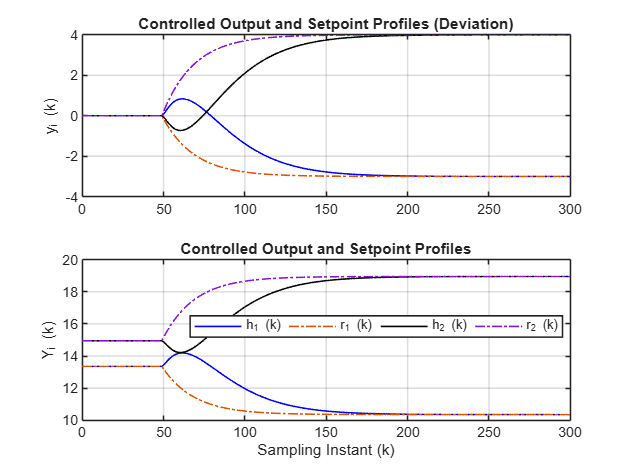

figure, subplot(211), 
plot(kT, yk(1,:), 'b',  kT, rk_f(1,:), '-.', kT, yk(2,:), 'k', kT, rk_f(2,:), '-.'), grid
title('Controlled Output and Setpoint Profiles (Deviation)'), ylabel('y_i (k)')
subplot(212), plot(kT, Yk(1,:), 'b',  kT, Rk_f(1,:), '-.', kT, Yk(2,:), 'k', kT, Rk_f(2,:), '-.'), grid
xlabel('Sampling Instant (k)'), ylabel('Y_i (k)')
legend('h_1 (k)', 'r_1 (k)', 'h_2 (k)', 'r_2 (k)', 'Orientation','horizontal','Location','Best')
title('Controlled Output and Setpoint Profiles')

**Manipulated input profiles**

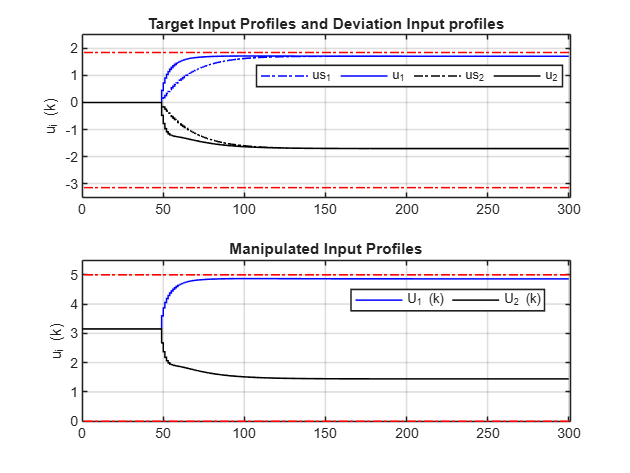

figure, subplot(211), stairs(kT, mpc.us_k(1,:)', '-.b','LineWidth',1), grid
hold on
stairs(kT, uk(1,:)', 'b','LineWidth',1)
stairs(kT, mpc.us_k(2,:)', '-.k','LineWidth',1)
stairs(kT, uk(2,:)', 'k','LineWidth',1)
stairs(u_limit, '-.r', 'LineWidth',1)
axis([0 N -3.5 2.5])
hold off
ylabel('u_i (k)'), title('Target Input Profiles and Deviation Input profiles')
legend( 'us_1', 'u_1', 'us_2', 'u_2', 'Orientation','horizontal','Location','Best')
subplot(212), stairs(kT, Uk(1,:)', 'b','LineWidth',1),  grid
hold on, stairs(kT, Uk(2,:)', 'k','LineWidth',1),
stairs(u_limit+QTank.Us', '-.r', 'LineWidth',1), hold off
axis([0 N 0 5.5]), ylabel('u_i (k)')
title('Manipulated Input Profiles')
legend( 'U_1 (k)', 'U_2 (k)','Orientation','horizontal','Location','Best')

**Disturbance input and Model Plant Mismatch profiles **

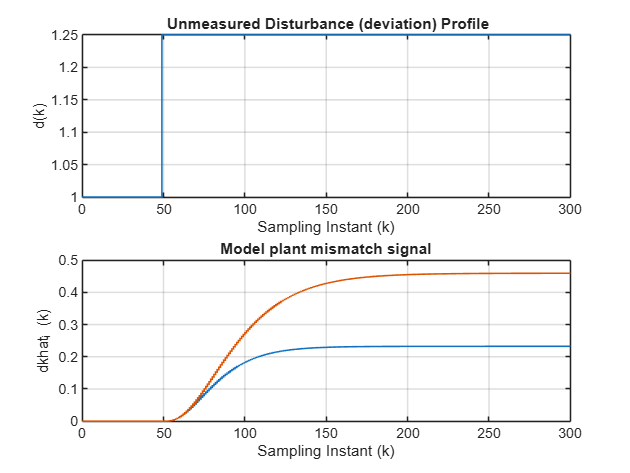

figure, subplot(211), stairs( kT, Dk,'LineWidth',1 ), grid
xlabel('Sampling Instant (k)'), ylabel('d(k)')
title(' Unmeasured Disturbance (deviation) Profile')
subplot(212), stairs( kT, mpc.dkhat_f','LineWidth',1 ), grid
xlabel('Sampling Instant (k)'), ylabel('dkhat_i (k)')
title('Model plant mismatch signal')

** System State profiles and MPC internal model profiles  **

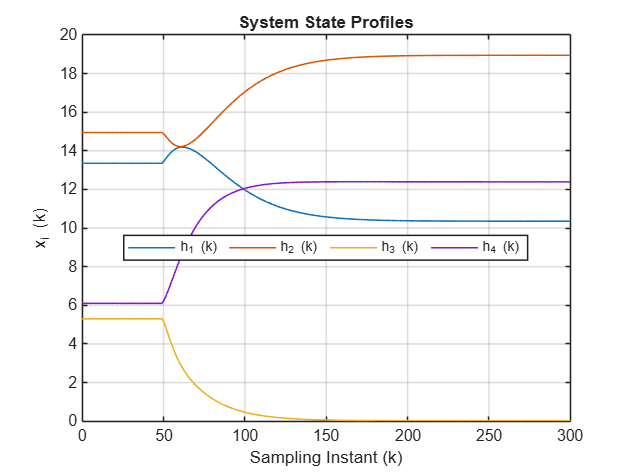

figure, plot(kT, Xk(1,:), kT, Xk(2,:), kT, Xk(3,:), kT, Xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('h_1 (k)', 'h_2 (k)', 'h_3 (k)', 'h_4 (k)', 'Orientation','horizontal','Location','Best')
title('System State Profiles')

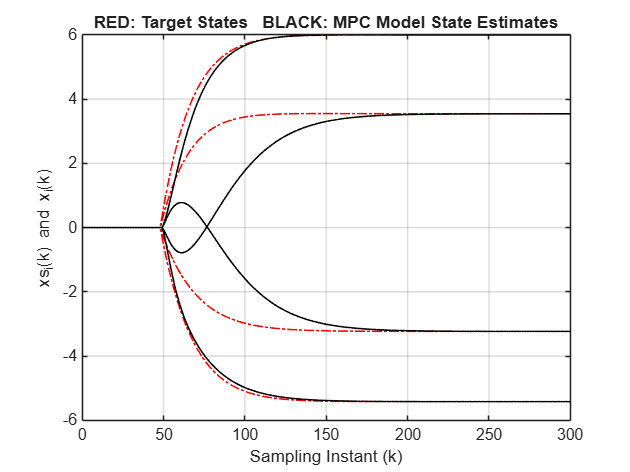

figure, plot(kT, mpc.xs_k, '-.r', kT, mpc.xkhat, 'k'), grid
title('RED: Target States   BLACK: MPC Model State Estimates')
xlabel('Sampling Instant (k)'), ylabel('xs_i(k) and x_i(k)')

From the results of simulation, we can see that the performance of the controller is almost same as compared to the first case, where control horizon was equal to the prediction horizon. For minimum phase operating point, with the tuning parameters set as above, for linear process the measured outputs reach the desired values very smoothly. 

**Task 5:** Now change the operating point to Non-minimum phase and and again observe the results. Do you observe that the performance become sluggish. We can improve the response by changing the prediction horizon.

**Task 6: **Go to Task 2 and try changing the prediction horizon. Observe the effect on results

**Task 7: **Go to Task 3 and try changing the weighting matrices. Observe the effect on results. Can we make the outputs reach the desired values faster? Try making 


$$W_y =100\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$$


**Task 8: **Try the above mentioned tasks by changing the plant simulation to nonlinear model in Task 4. What do you observe? Observe the plant model mismatch signal, it increases with nonlinear process simulation, however the controller can predict this and desired performance can be achieved.

Task 5: Change the model used in MPC formulation and observe the results

## Output Tracking Vanilla MPC

    Now, let us derive some variants of vanilla MPC that are popularly used in the industry. Consider a special case where the weighting matrix is chosen as $W_x =C^T W_y C$

${\left(z\left(k+j\right)-x_s \left(k\right)\right)}^T {C^T W}_y C\left(z\left(k+j\right)-x_s \left(k\right)\right)={\left(\textrm{Cz}\left(k+j\right)-{\textrm{Cx}}_s \left(k\right)\right)}^T W_y \left(\textrm{Cz}\left(k+j\right)-{\textrm{Cx}}_s \left(k\right)\right)$  ------(28)

where $W_y$ is a positive definite matrix. Defining j-step ahead predicted output, 

$\begin{array}{l}
\hat{x} \left(k+j+1\right)=\Phi \hat{x} \left(k+j\right)+\Gamma u\left(k+j|k\right)\\
\hat{y} \left(k+i\right)=\textrm{Cz}\left(k+j\right)
\end{array}$  ------(29)

and time varying output reference signal, $r_s \left(k\right)=\;{\textrm{Cx}}_s \left(k\right)$, the state error related terms in the cost function can we rewritten as follows 

${{\left\|z\left(k+p\right)-x_s \left(k\right)\right\|}^2 }_{W_{\infty } } +\sum_{j=0}^{p-1} \left\lbrace {{\left\|z\left(k+j\right)-r_s \left(k\right)\right\|}^2 }_{W_x } \right\rbrace$=${{\left\|\hat{y} \left(k+p\right)-r_s \left(k\right)\right\|}^2 }_{W_{y,\infty } } +\sum_{j=0}^{p-1} \left\lbrace {{\left\|\hat{y} \left(k+j\right)-r_s \left(k\right)\right\|}^2 }_{W_y } \right\rbrace$  ------(30)

where $W_{y,\infty } =C^T W_{\infty } C$ and $r_s \left(k\right)$represents some target setpoint for the controlled output.  Alternatively, the matrix $W_{y,\infty }$ appearing on the R.H.S. of the above equation can be found by solving discrete Lyapunov equation  

${\Phi^T W_{y,\infty } \Phi -W}_{y,\infty } ={-C}^T W_y C$ ------(31)

Using this transformation, we can define the following variant of vanilla MPC loss function 

$J\left\lbrack y\left(k\right),\hat{x} \left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack ={{\left\|\hat{y} \left(k+p\right)-r_s \left(k\right)\right\|}^2 }_{W_{y,\infty } } +\sum_{j=0}^{p-1} \left\lbrace {{\left\|\hat{y} \left(k+j\right)-r_s \left(k\right)\right\|}^2 }_{W_y } +{{\left\|u\left(k+j|k\right)-u_s \left(k\right)\right\|}^2 }_{W_u } \right\rbrace$  ------(32)

which is similar to the loss function popularly used in the industry. Thus, choosing $W_x =C^T W_y C$ in the vanilla MPC developed in Lesson 2 is equivalent to using the output tracking controller. 

What is the significance of output tracking control? Till now we have assumed that a mechanistic model is available for control. We developed a linear approximation of the model and then used for controller synthesis. However, in many industrial settings a well developed and reliable mechanistic model may not be available. In such cases, a state space model of the form 

  $\begin{array}{l}
\chi \left(k+1\right)=\tilde{\Phi} \chi \left(k\right)+\tilde{\Gamma} u\left(k\right)\\
y\left(k\right)=\tilde{C} \;\chi \left(k\right)\;
\end{array}$  ------(33)

 is identified from perturbation data collected from the plant.  Here, $\chi \in R^{n_x }$ represents an artificial state vector (a mathematical struct) that may not have any physical meaning. Note that, in general, $n_x$ may not be equal to *n. * Also, matrices$\left(\tilde{\Phi} ,\;\tilde{\Gamma} ,\;\tilde{C} \right)$ in equation (36) are different from matrices $\left(\Phi ,\Gamma ,C\right)$ obtained from linearization. Only common signals between the linearized perturbation model and the identified state space model are $\left(y\left(k\right),u\left(k\right)\right)$.

 Approach to identify such model matrices $\left(\tilde{\Phi} ,\;\tilde{\Gamma} ,\;\tilde{C} \right)$from data will be discussed later in [Module 8](matlab:open('../8. System_Identification/L01_Introduction_to_System_Identification.mlx')). Here we assume that a model of form (33) identified using data generated in the neighborhood of operating point $\left(X_s ,U_s ,D_s \right)$ is available with us. We formulate the vanilla output tracking MPC using (33) as follows 


$$\;$$
  
$${\mathrm{U}}_p^* \left(k\right)=\overset{\arg \;\min }{{\mathrm{U}}_p \left(k\right)} \;\;\;J\left\lbrack y\left(k\right),\hat{\chi} \left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack$$
  

$J\left\lbrack y\left(k\right),\hat{x} \left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack ={{\left\|\hat{y} \left(k+p\right)-r_s \left(k\right)\right\|}^2 }_{W_{y,\infty } } +\sum_{j=0}^{p-1} \left\lbrace {{\left\|\hat{y} \left(k+j\right)-r_s \left(k\right)\right\|}^2 }_{W_y } +{{\left\|u\left(k+j|k\right)-u_s \left(k\right)\right\|}^2 }_{W_u } +{{\left\|\Delta u\left(k+j|k\right)\right\|}^2 }_{W_u } \right\rbrace$  ----(34)

Subject To

$\begin{array}{l}
z\left(k+j+1\right)=\tilde{\Phi} z\left(k+j\right)+\tilde{\Gamma} u\left(k+j|k\right)\;\;\textrm{for}\;j=0,1,\ldotp \ldotp \ldotp ,p-1\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{with}\;\textrm{initial}\;\textrm{condition}\;\;z\left(k\right)=\chi \left(k\right)
\end{array}$  -------(35)

$\hat{y} \left(k+i\right)=\textrm{Cz}\left(k+j\right)$  ------(36)

     $u_L \le u\left(k+j|k\right)\le u_H$   for$j=0,1,2,\ldotp \ldotp \ldotp \ldotp p-1$   ------(37)

Note that the model predictions have been  carried out using $\left(\tilde{\Phi} ,\;\tilde{\Gamma} ,\;\tilde{C} \right)$ and initialized using $\chi \left(k\right)$, which is computed as 

  $\chi \left(k\right)=\tilde{\Phi} \chi \left(k-1\right)+\tilde{\Gamma} u\left(k-1\right)$  ------(38)

More over, the target states, inputs and reference signals are computed using $\left(\tilde{\Phi} ,\;\tilde{\Gamma} ,\;\tilde{C} \right)$ as follows 

 $\begin{array}{l}
\chi_s \left(k\right)={\left(I-\tilde{\Phi} \right)}^{-1} \tilde{\Gamma} u_s \left(k\right)\\
u_s \left(k\right)={\left(\tilde{C} {\left(I-\tilde{\Phi} \right)}^{-1} \tilde{\Gamma} \right)}^{-1} \;\left(r_f \left(k\right)-\hat{d_f } \left(k\right)\right)
\end{array}$ ------(39)

 When $u_s \left(k\right)$ computed using (23) exceed input bounds, or when $l\not= m$, the target state can be computed by solving the following optimization problem

$\min_{u_s \left(k\right)} \left\lbrace {\left(r_f \left(k\right)-y_s \left(k\right)\right)}^T \;W_{\textrm{ys}} \left(r_f \left(k\right)-y_s \left(k\right)\right)\right\rbrace$   ------(40)

subject to,

$y_s \left(k\right)=\tilde{G} u_s \left(k\right)+{\hat{d} }_f \left(k\right)$ ------(41) 

$u^L \le u_s \left(k\right)\le u^H$ ------ (42)

where $\tilde{G} =\tilde{C} {\left(I-\tilde{\Phi} \right)}^{-1} \tilde{\Gamma}$ . Here, the mismatch signal is computed as follows 

$\hat{d} \left(k\right)=y\left(k\right)-\hat{y} \left(k\right)=y\left(k\right)-C\;\chi \left(k\right)$ ------(43)

where $\chi \left(k\right)$ is given by equation (39) and 

${\hat{d} }_f \left(k+1\right)=\Phi_d \;{\hat{d} }_f \left(k\right)+\left({I-\Phi }_s \right)\;\hat{d} \left(k\right)$  ------(44)

         To demonstrate efficacy of identified state space model, we demonstrate control of Q-Tank process using an [identified state space model](matlab:open('../8. System_Identification/L10_OE_Model_QTank.mlx')) with matrices which have different dimensions as compared to the linearized model. To design the controller, we set $W_x =$${\tilde{\left(C\right)} }^T W_y \tilde{C}$ and derive a QP formulation that solves the output tracking MPC formulation. 

### Closed Loop Simulation for Q tank Process with Output Tracking Vanilla MPC

In this exercise, we demonstrate the output tracking vanilla MPC implemented on Q Tank process. Users can run the section to observe the tracking control

 
clear all 

N = 451 ;      % Simulation run time

global QTank U_k D_k


**Task 1:** Selection of operating point

operating_pt=2;

% Load quadruple tank parameters and steady state 
% The following file loads QTank data structure 
if operating_pt==1
load QTank_MinPhase_Model
  load QTank_OESS_MP.mat
else
 load QTank_NonMinPhase_Model 
  load QTank_OESS_NMP.mat
end
% Initialization of linear discrete time model for plant simulation 

phy = QTank.phy ; 
gam = QTank.gama_u ;
gam_d = QTank.gama_d ; 
C_mat = QTank.C_mat ;
[n_op, nx ] = size(C_mat)  ;         
[n_st,n_ip] = size(gam) ;

As discussed earlier, we can either use an identified model or first principles model for internal model of MPC. We can set the variable **use_id_mod** to Identified model or linear perturbation model obtained from First Principle model. The identified model is a  Black box state space model from input output data using System Identification Toolbox. Note that the number of states for plant and for MPC internal model need not be equal. Note that the identified model is quite different than the linearized model that is obtained from the first principles model. They can be accessed as mpc.phy, mpc.gam, mpc.C_mat

**Task 2: **Select First Principle Model for MPC formulation

use_id_mod =1 ; 

if (use_id_mod)
    mpc.phy =model_oe_ss.A;
    mpc.gam =model_oe_ss.B ;
    mpc.C_mat =model_oe_ss.C ;
else
    % Internal model for MPC 
    mpc.phy = QTank.phy ;
    mpc.gam = QTank.gama_u ;
    mpc.C_mat = QTank.C_mat ;
end
% No. states for plant and for MPC internal model need not be equal 

[mpc.n_st,mpc.n_ip] = size(mpc.gam) ;
[mpc.n_op, nx] = size(mpc.C_mat) ;


** MPC Tuning Parameters**

**Task 3:** Prediction horizon for MPC is set to 50.  Gen_QP_Matrices_Tracking_delU is the function used to compute matrices required for QP formulation.

mpc.n_pred = 50 ;   % Set Prediction interval >= 50. Setting it to 40 leads to infeasible QP at k = 0  

**Task 4: **Weighting matrices are as given below.

 $W_{\Delta u} =100\times \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$  and  $W_u =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$

$W_y =10\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$ and 


$$W_x =C^T W_y C$$


mpc.Wu = 1* eye(n_ip) ; % Input weighting matrix
mpc.Wdelu = 100* eye(n_ip) ; % Input weighting matrix. Note: Effect is seen only if large weighting is used 
Wy = 10 * eye(n_op);  % Output weighting matrix
mpc.Wx = mpc.C_mat' * Wy * mpc.C_mat ; % State weighting matrix 
mpc.u_H = [5 5]' - QTank.Us ;  % Physical Input bounds low are 0 and 5 Volts 
mpc.u_L = [0 0]' - QTank.Us ;  
mpc.deluL = [] ; mpc.deluH = [] ; 

% Generate MPC QP matrices 

[mpc] = Gen_QP_Matrices_Tracking_delU( mpc ) ;

% Initialization of Controller related parameters and matrices 

mpc.xs_k = zeros(mpc.n_st,N);   % Array to save target states 
mpc.us_k = zeros(n_ip,N) ;  % Array to save target inputs 
mpc.xkhat = zeros(mpc.n_st,N);
mpc.yhat = zeros(n_op,N) ; 
mpc.dkhat = zeros(n_op,N);     % Model plant mismatch signal 
mpc.dkhat_f = zeros(n_op,N); % Filtered Model plant mismatch signal 
mpc.phy_d = 0.9 * eye(n_op) ;  % Disturbance filter parameter 

% Matrices for simulating system dynamics 
xk = zeros(n_st,N);
uk = zeros(n_ip,N) ;
yk = zeros(n_op,N);
yk(:,1) = C_mat * xk(:,1) ; 
dk = zeros(1,N) ;
rk_f = zeros(n_op,N);  
phy_r = 0.9 * eye(n_op) ;  % Setpoint filter parameters 

** Disturbance input **

A time varying disturbance input signal is generated such that initially it is set to zero. Then changed from it's initial value to 0.5 for ($\left.k\ge 250\right)\;$.

% Disturbance input 
for k = 1:N
    if ( k < 250 )
        dk(k) = 0 ;
    else
        dk(k) = 0.5 ;  % Introduce disturbance change at k = 250
    end
end

options=optimoptions('quadprog', 'display', 'off');

% Closed loop simulations using QP-LMPC under model-plant mismatch 
% Setpoint change followed by disturbance rejection 

**Task 5:** Select Plant_Sim as Nonlinear for simulating Q Tank process using a nonlinear ODE model.

Plant_Sim =1  ;
for k = 1:N-1
   
    % Controller calculations at instant k 
    kT(k) = (k-1);


A time varying reference input signal is generated such that initially it is set to zero for both the outputs.  Then changed from it's initial value to$r\left(k\right)=\left\lbrack -2\ldotp 5\;2\right\rbrack$ for $k\ge 50$. Set point is also filtered as discussed earlier.

    if ( k < 50 )
        rk = [0 0]' ;
    else
       % rk =  [ -1.5 1.5 ]' ;
         rk =  [ -1 1]' ;
    end
    rk_f(:,k+1) = phy_r * rk_f(:,k) + (eye(n_op) - phy_r) * rk   ;  %Setpoint filter

    % MPC implementation at instant k (Reusing the function developed in the previous section) 
    [mpc, u_k ] = MPCQP_StateSpace_delU( mpc, yk(:,k), rk_f(:,k+1), k ) ;
    mpc.uk = u_k ;


    Quadruple tank Plant Simulation from k to k+1 is carried out either by linear discrete time model or nonlinear ODE model.


    if (Plant_Sim )
        % Using discrete linear model
        uk(:,k) = mpc.uk ;
        xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) + gam_d * dk(k)  ;
        yk(:,k+1) = C_mat * xk(:,k+1) ;
    else
        % Using discrete nonlinear model
        uk(:,k) = mpc.uk ;
        U_k = QTank.Us + mpc.uk ;
        D_k =  QTank.Ds + dk(k)  ;
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;   % Nonlinear plant simulation
        xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
        yk(:,k+1) = C_mat * xk(:,k+1) ;
    end

end
uk(:,N) = uk(:,N-1) ;
kT(N) = N-1 ;
mpc.dkhat(:,N) = mpc.dkhat(:,N-1) ; 
mpc.us_k(:,N) = mpc.us_k(:,N-1) ;
mpc.xs_k(:,N) = mpc.xs_k(:,N-1) ;

**Display Simulation Results**

Observe the figures below for state profiles tracking control, time varying set-point tracking control for outputs, inputs, model plant mismatch signal, Unmeasured disturbance input, Target State Profiles and Target Input Profiles.

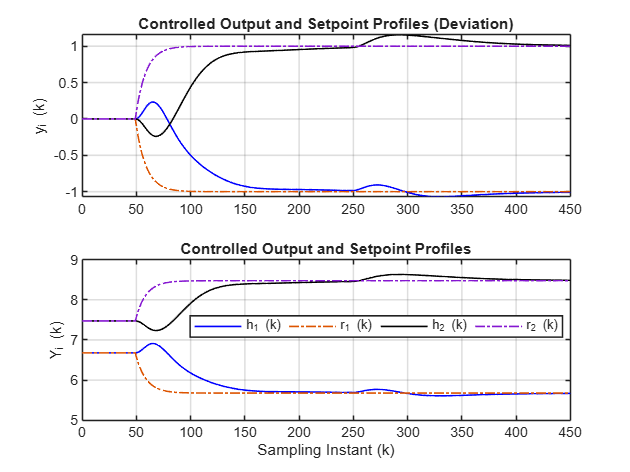


% Display results
Set_Graphics_Parameters ;
Xk = QTank.Xs + xk ;   Uk = QTank.Us + uk ; Dk = QTank.Ds + dk ;
Yk = yk + C_mat * QTank.Xs ;  Rk_f = rk_f + C_mat * QTank.Xs ;
u_limit = [mpc.u_L(1)*ones(N,1) mpc.u_H(1)*ones(N,1)]  ;

% Controlled output profiles 
figure, subplot(211), 
plot(kT, yk(1,:), 'b',  kT, rk_f(1,:), '-.', kT, yk(2,:), 'k', kT, rk_f(2,:), '-.'), grid
title('Controlled Output and Setpoint Profiles (Deviation)'), ylabel('y_i (k)')
subplot(212), plot(kT, Yk(1,:), 'b',  kT, Rk_f(1,:), '-.', kT, Yk(2,:), 'k', kT, Rk_f(2,:), '-.'), grid
xlabel('Sampling Instant (k)'), ylabel('Y_i (k)')
legend('h_1 (k)', 'r_1 (k)', 'h_2 (k)', 'r_2 (k)', 'Orientation','horizontal','Location','Best')
title('Controlled Output and Setpoint Profiles')

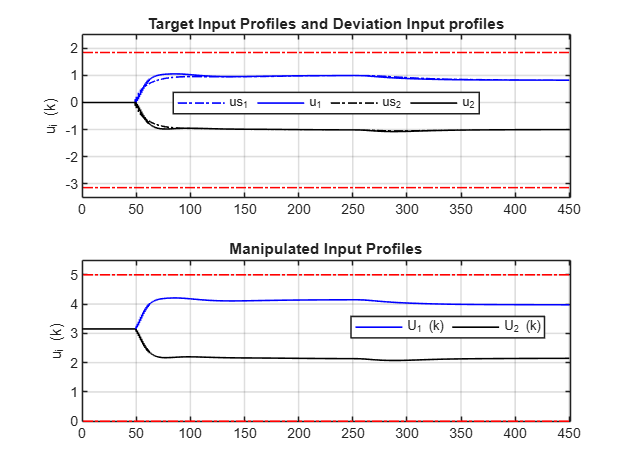


%Manipulated input profiles
figure, subplot(211), stairs(kT, mpc.us_k(1,:)', '-.b','LineWidth',1), grid
hold on
stairs(kT, uk(1,:)', 'b','LineWidth',1)
stairs(kT, mpc.us_k(2,:)', '-.k','LineWidth',1)
stairs(kT, uk(2,:)', 'k','LineWidth',1)
stairs(u_limit, '-.r', 'LineWidth',1)
axis([0 N -3.5 2.5])
hold off
ylabel('u_i (k)'), title('Target Input Profiles and Deviation Input profiles')
legend( 'us_1', 'u_1', 'us_2', 'u_2', 'Orientation','horizontal','Location','Best')
subplot(212), stairs(kT, Uk(1,:)', 'b','LineWidth',1),  grid
hold on, stairs(kT, Uk(2,:)', 'k','LineWidth',1),
stairs(u_limit+QTank.Us', '-.r', 'LineWidth',1), hold off
axis([0 N 0 5.5]), ylabel('u_i (k)')
title('Manipulated Input Profiles')
legend( 'U_1 (k)', 'U_2 (k)','Orientation','horizontal','Location','Best')

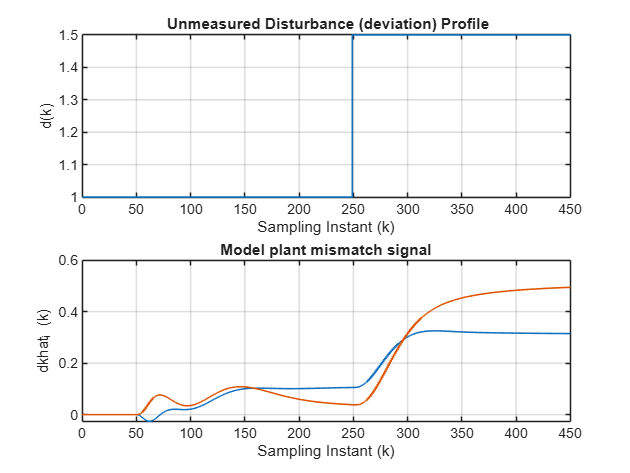


% Disturbance input and Model Plant Mismatch profiles 
figure, subplot(211), stairs( kT, Dk,'LineWidth',1 ), grid
xlabel('Sampling Instant (k)'), ylabel('d(k)')
title(' Unmeasured Disturbance (deviation) Profile')
subplot(212), stairs( kT, mpc.dkhat_f','LineWidth',1 ), grid
xlabel('Sampling Instant (k)'), ylabel('dkhat_i (k)')
title('Model plant mismatch signal')

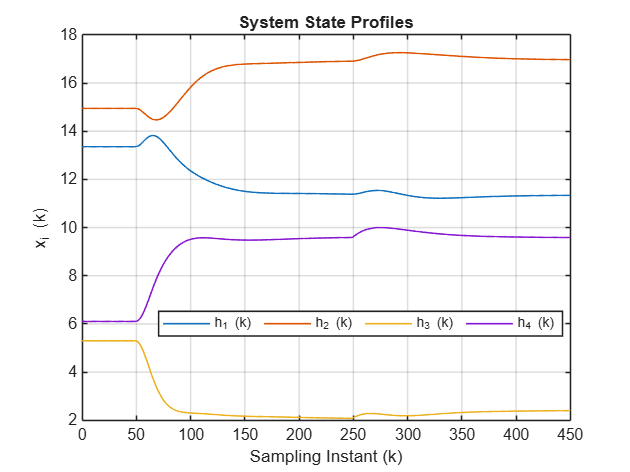


% System State profiles and MPC internal model profiles  
figure, plot(kT, Xk(1,:), kT, Xk(2,:), kT, Xk(3,:), kT, Xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('h_1 (k)', 'h_2 (k)', 'h_3 (k)', 'h_4 (k)', 'Orientation','horizontal','Location','Best')
title('System State Profiles')

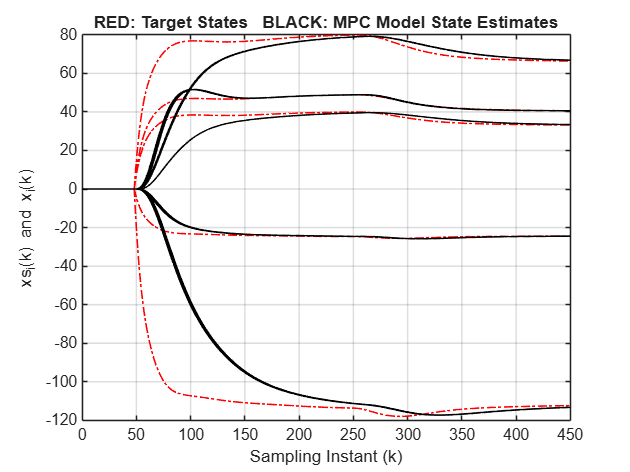

figure, plot(kT, mpc.xs_k, '-.r', kT, mpc.xkhat, 'k'), grid
title('RED: Target States   BLACK: MPC Model State Estimates')
xlabel('Sampling Instant (k)'), ylabel('xs_i(k) and x_i(k)')

From the results of simulation, for minimum phase operating point, with the tuning parameters set as above, for linear process the measured outputs reach the desired values very smoothly. It is also rejecting the disturbances. 

**Task 6:** Now change the operating point to Non-minimum phase and and again observe the results. Do you observe that the performance become sluggish. We can improve the response by changing the prediction horizon.

**Task 7: **Go to Task 3 and try changing the prediction horizon. Observe the effect on results

**Task 8: **Go to Task 4 and try changing the weighting matrices. Observe the effect on results. Can we make the outputs reach the desired values faster? Try making 


$$W_y =100\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$$


Do you see the improvement in performance?

**Task 9: **Try the above mentioned tasks by changing the plant simulation to nonlinear model in Task 4. What do you observe? Observe the plant model mismatch signal, it increases with nonlinear process simulation, however the controller can predict this and desired performance can be achieved.

**Task 10: **Now change the model used for MPC formulation to identified model and perform the closed loop simulations for minimum phase operating point with linear model and the original MPC tuning parameter settings. Change the operating point to non-minimum phase. Again observe the performance. You may need to change the tuning parameters again. 

Also try with nonlinear plant simulation.

## Conclusion

In this lesson we have introduced some important features available in the industrial implementation of MPC. Instead of including hard constraints on the rate of change of inputs, it is possible to include a penalty on the rate of change of inputs in the MPC loss function. The associated weighting matrix can be used to reduce sudden large variations in the manipulated inputs. Also, introduction of control horizon reduces the dimension of the QP problem and the resulting closed loop behavior is not too different from the the closed loop behavior obtained using equal control and prediction horizons.  

The output tracking MPC formulation presented in the last section makes a significant change from the conceptual viewpoint. We have shown that a black-box model can be used to control a nonlinear system in the neighborhood of a stable operating point. This eliminates the need to use a mechanistic model for developing an MPC scheme and expands applicability of MPC to a much larger class of industrial systems. 

Note that the vanilla MPC variants developed in this section can be used only when all the eigenvalues of the state transition matrix are strictly inside the unit circle. We will have to do more work to expand the applicability of the vanilla MPC to unstable systems. This extension will be discussed later in the course. 